**ABBD Matrix Calculation Code**

**Datasheet Syntax**

Row 1: Thickness    <value>

Row 2 : numLayers    <value>

Row 3: Temperature (T)    <value>

Row 4: Moisture (M)    <value>

Row 5 : --blank--

Row 6 : (Headers) Thickness    Angle    E1    E2    nu12    nu21    G12    alpha_xx    alpha_xy    alpha_yy    Tref    b_xx    b_xy    b_yy    Mref

Row 7+: Lamina parameter values as per row 4

**Q Matrix Calculator (Stiffness Matrix of a lamina)**

Input: E1    E2    nu12    nu21    G12

Output: Q (or C)

function [Q] = Q_matrix_calculator(E1, E2, nu12, nu21, G12)
    Q = zeros(3, 3);
    Q(1, 1) = (-E1)/(nu12*nu21 - 1);
    Q(1, 2) = (-nu12*E2)/(nu12*nu21 - 1);
    Q(1, 3) = 0;
    Q(2, 1) = (-nu21*E1)/(nu12*nu21 - 1);
    Q(2, 2) = (-E2)/(nu12*nu21 - 1);
    Q(2, 3) = 0;
    Q(3, 1) = 0;
    Q(3, 2) = 0;
    Q(3, 3) = G12;
end

**Qbar Matrix Calculator (Transformed Stiffness Matrix of a lamina)**

Input: Q    theta

Output: Qbar

function [Qbar] = Qbar_matrix_calculator(Q, theta)
    Qbar = zeros(3, 3);
    m = cos(deg2rad(theta));
    n = sin(deg2rad(theta));

    Qbar(1, 1) = Q(1, 1)*(m^4) + 2*(Q(1, 2) + 2*Q(3, 3))*(n^2)*(m^2) + Q(2, 2)*(n^4);
    Qbar(1, 2) = (Q(1, 1) + Q(2, 2) - 4*Q(3, 3))*(n^2)*(m^2) + Q(1, 2)*(n^4 + m^4);
    Qbar(1, 3) = (Q(1, 1) - Q(1, 2) - 2*Q(3, 3))*n*(m^3) + (Q(1, 2) - Q(2, 2) + 2*Q(3, 3))*(n^3)*m;
    Qbar(2, 1) = Qbar(1, 2);
    Qbar(2, 2) = Q(1, 1)*(n^4) + 2*(Q(1, 2) + 2*Q(3, 3))*(n^2)*(m^2) + Q(2, 2)*(m^4);
    Qbar(2, 3) = (Q(1, 1) - Q(1, 2) - 2*Q(3, 3))*(n^3)*m + (Q(1, 2) - Q(2, 2) + 2*Q(3, 3))*n*(m^3);
    Qbar(3, 1) = Qbar(1, 3);
    Qbar(3, 2) = Qbar(2, 3);
    Qbar(3, 3) = (Q(1, 1) + Q(2, 2) - 2*Q(1, 2) - 2*Q(3, 3))*(n^2)*(m^2) + Q(3, 3)*(n^4 + m^4);
end

**A, B, D Matrices Calculator Code**

Input: Location of the csv file of composite parameters (as defined above)

Output: 6x6 Composite Stiffness Matrix [A, B; B, D]

function [composite_stiffness] = ABBD_matrix_calculator (path)
    % Extracting data from path
    data = readcell(path);

    % Initialisation of A, B, D and final composite matrices
    A = zeros(3, 3);
    B = zeros(3, 3);
    D = zeros(3, 3);
    composite_stiffness = zeros(6, 6);

    %Extracting composite parameters
    thickness = data{1, 2};
    numlayers = data{2, 2};

    z_tillnow = -thickness/2;

    for k = 1:numlayers
        % Extracting layer information
        layer_thickness = data{6 + k, 1};
        theta = data{6 + k, 2};
        E1 = data{6 + k, 3};
        E2 = data{6 + k, 4};
        nu12 = data{6 + k, 5};
        nu21 = data{6 + k, 6};
        G12 = data{6 + k, 7};
        
        Q = Q_matrix_calculator(E1, E2, nu12, nu21, G12);
        Qbar = Qbar_matrix_calculator(Q, theta);

        % Adding layer contribution to A, B, D matrices
        for i = 1:3
            for j = 1:3
                A(i, j) = A(i, j) + Qbar(i, j)*(layer_thickness);
                B(i, j) = B(i, j) + (0.5) * Qbar(i, j)*((z_tillnow + layer_thickness)^2 - z_tillnow^2);
                D(i, j) = D(i, j) + (1/3) * Qbar(i, j)*((z_tillnow + layer_thickness)^3 - z_tillnow^3);
            end
        end

        z_tillnow = z_tillnow + layer_thickness;
    end

    % Defining Composite stiffness matrix
        composite_stiffness(1:3, 1:3) = A;
        composite_stiffness(1:3, 4:6) = B;
        composite_stiffness(4:6, 1:3) = B;
        composite_stiffness(4:6, 4:6) = D;
end

**Wing Box Analysis**

% Given Parameters

MTOW = 580; % Maximum TakeOff Weight (kg)
g = 9.81; % gravitational acceleration (m/s^2)
W = MTOW * g; % Weight of aircraft (N)
n_limit = 3.8; % Limit Load Factor
n_ultimate = 1.5 * n_limit; % Ultimate Load Factor
delta_tip = 0.1; % Maximum allowed deflection at wing tip at limit load (m)

b = 11; % Wing span (m)
s = b/2; % Semi wing span (m)
c = 1.23; % Chord length (m)
NACA_number = 2412; % NACA Airfoil number

x_frontSpar = 0.25*c;
x_rearSpar = 0.65*c;



% ABBD Matrices from Composites

M_sparcap = ABBD_matrix_calculator("C:\Users\anutt\OneDrive\Documents\Courses\AE673\Project\datasheet_sparcap.xlsx");
M_skin = ABBD_matrix_calculator("C:\Users\anutt\OneDrive\Documents\Courses\AE673\Project\datasheet_skin.xlsx");
M_sparweb = ABBD_matrix_calculator("C:\Users\anutt\OneDrive\Documents\Courses\AE673\Project\datasheet_sparweb.xlsx");

data_sparcap = readcell("C:\Users\anutt\OneDrive\Documents\Courses\AE673\Project\datasheet_sparcap.xlsx");
data_skin = readcell("C:\Users\anutt\OneDrive\Documents\Courses\AE673\Project\datasheet_skin.xlsx");
data_sparweb = readcell("C:\Users\anutt\OneDrive\Documents\Courses\AE673\Project\datasheet_sparweb.xlsx");



% Helper Functions

function [wf, wr] = SparwebWidth_Calculator (NACA_number, c, xf, xr)
    t = (mod(NACA_number, 100) / 100) * c;
    y_t = @(x) 5*t*(0.2969*sqrt(x) - 0.126*x - 0.3516*x^2 + 0.2843*x^3 - 0.1015*x^4);
    wf = 2 * y_t(xf/c);
    wr = 2 * y_t(xr/c);
end

function [EI] = EI_calculator (M, delta_tip, s)
    integrand = @(y) M(y) .* (s - y);
    K = integral(integrand, 0, s);
    EI = K / delta_tip;
end

function [E_sparcap] = E_sparcap_Calculator (M_sparcap, t_sparcap)
    A_sparcap = M_sparcap(1:3, 1:3);
    S_sparcap = inv(A_sparcap);
    E_sparcap = 1 / (t_sparcap * S_sparcap(1, 1));
end

function [wf, wr] = SparcapWidth_Calculator (EI, E_sparcap, width_frontSparweb, width_rearSparweb, t_sparcap)
    I_spar = EI/E_sparcap;
    total_width_sparcap = I_spar / ((0.3 * width_frontSparweb^2 + 0.2 * width_rearSparweb^2) * t_sparcap);
    wf = 0.6 * total_width_sparcap;
    wr = 0.4 * total_width_sparcap;
end

function [GJ] = GJ_Calculator (hf, hr, rib_length, A66_skin, A66_sparweb)
    Am = 0.5 * (hf + hr) * rib_length;
    val = (2 * rib_length) / A66_skin + (hf + hr) / A66_sparweb;
    GJ = (4*Am^2)/val;
end

function [E_skin] = E_skin_Calculator (M_skin, t_skin)
    A_skin = M_skin(1:3,1:3);   % N/m
    S_skin = inv(A_skin);       % compliance matrix
    E_skin = 1 / (t_skin * S_skin(1,1));   % Pa 
end

function [ribs_spacing] = RibsSpacing_Calculator (L, hf, hr, t_skin, E_skin)
    q = (0.5*L)/(hf + hr);
    tau = q/t_skin;
    ribs_spacing = 5 * t_skin * sqrt(E_skin / tau);
end



% Derived Quantities

t_sparcap = data_sparcap{1,2};
t_skin = data_skin{1,2};
t_sparweb = data_sparweb{1,2};

[width_frontSparweb, width_rearSparweb] = SparwebWidth_Calculator(NACA_number, c, x_frontSpar, x_rearSpar);
rib_length = x_rearSpar - x_frontSpar;

L_limit = n_limit * W; % Lift at limit load (N)
L_ultimate = n_ultimate * W; % Lift at ultimate load (N)

V = @(y) (L_limit/pi) * (acos(y/s) - (y/s).*sqrt(1 - (y/s).^2));
M = @(y) ((b*L_limit)/(3*pi)) * (1 - (y/s).^2).^1.5 - y.*V(y);

EI = EI_calculator(M, delta_tip, s); % Bending Stiffness (N/m^2)

E_sparcap = E_sparcap_Calculator(M_sparcap, t_sparcap);

[width_frontSparcap, width_rearSparcap] = SparcapWidth_Calculator (EI, E_sparcap, width_frontSparweb, width_rearSparweb, t_sparcap);

GJ = GJ_Calculator(width_frontSparcap, width_rearSparcap, rib_length, M_skin(3, 3), M_sparweb(3, 3));

E_skin = E_skin_Calculator(M_skin, t_skin);

ribs_spacing = RibsSpacing_Calculator(L_limit, width_frontSparcap, width_rearSparcap, t_skin, E_skin);


% Printing Results

disp("Data regarding wingbox dimension: --");

Data regarding wingbox dimension: --


t_sparcap

t_sparcap = 0.0040

t_sparweb

t_sparweb = 0.0040

t_skin

t_skin = 0.0020

width_frontSparcap

width_frontSparcap = 0.2747

width_rearSparcap

width_rearSparcap = 0.1831

rib_length

rib_length = 0.4920

rib_spacing

rib_spacing = 0.1080


disp("------------------------------")

------------------------------


disp("Property Data: --");

Property Data: --


L_limit

L_limit = 2.1621e+04

EI

EI = 1.7394e+06

GJ

GJ = 5.8972e+05

E_sparcap

E_sparcap = 1.1207e+11

E_skin

E_skin = 1.6911e+10


disp("------------------------------")

------------------------------


disp("At root values: --");

At root values: --


V_root = V(0)

V_root = 1.0811e+04

M_root = M(0)

M_root = 2.5235e+04

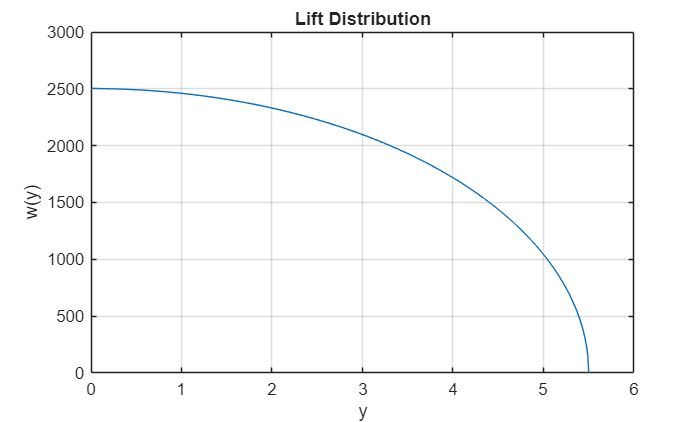


% Distribution Plots
y = 0:1e-2:s;

figure;
plot(y, ((4*L_limit)/(pi*b)) * sqrt(1 - y.^2/s^2));
xlabel("y");
ylabel("w(y)");
title("Lift Distribution");
grid on;

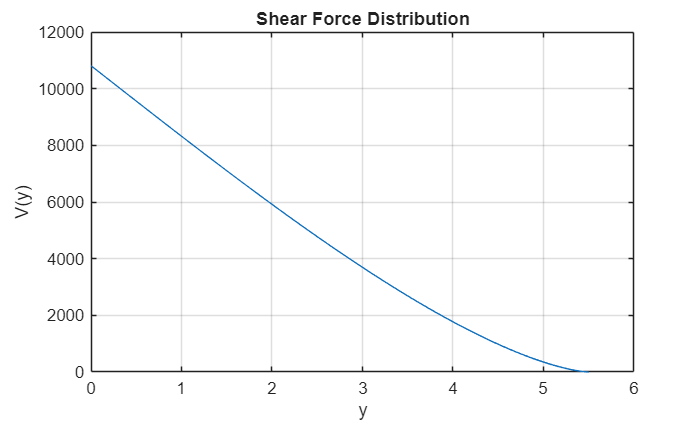


figure;
plot(y, V(y));
xlabel("y");
ylabel("V(y)");
title("Shear Force Distribution");
grid on;

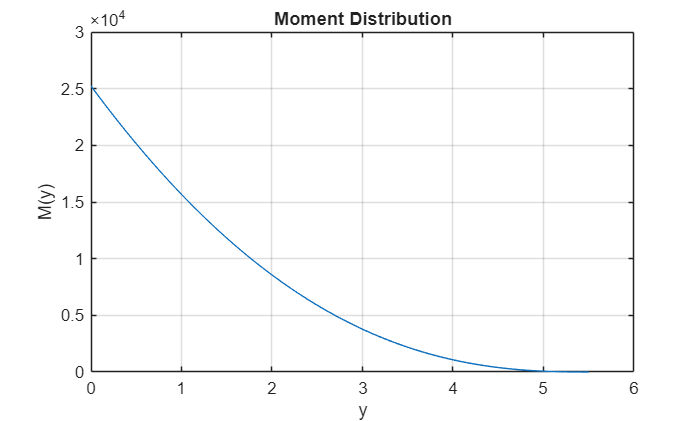


figure;
plot(y, M(y));
xlabel("y");
ylabel("M(y)");
title("Moment Distribution");
grid on;